wheel_calibration_data = readmatrix("table-rocky-calibration.csv")

wheel_calibration_data =          0         0
    0.3400    0.3100
    0.4900    0.4900
    0.6700    0.6600
    0.7500    0.7300
    0.8100    0.7900
    0.8400    0.8100
    0.8500    0.8200
    0.8900    0.8500
    0.8900    0.8500


frequency_calibration_data = readmatrix("FrequencyCalibrarionData.csv")

frequency_calibration_data =    -1.8500
   -1.8800
   -1.9100
   -1.9200
   -1.9300
    1.6600
    1.6600
    1.6700
    1.6900
    1.7200


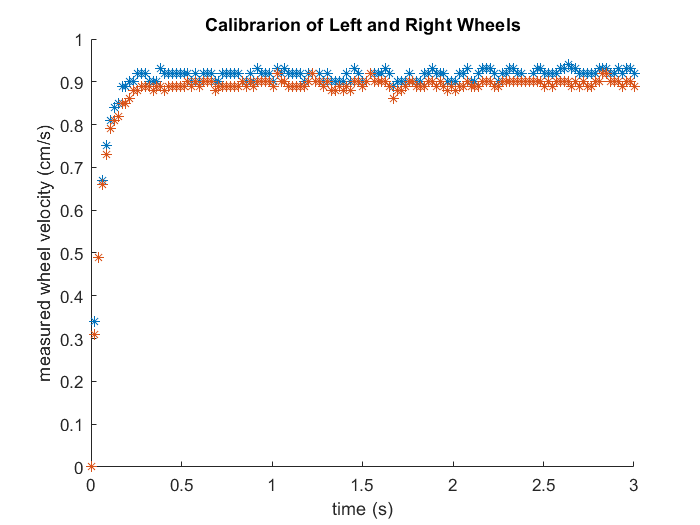



time = linspace(0, 3, 141);
l_wheel = wheel_calibration_data(:,1);
r_wheel = wheel_calibration_data(:,2);

clf; hold on; 
plot(time, l_wheel, "*");
plot(time, r_wheel, "*");

title("Calibrarion of Left and Right Wheels");
xlabel("time (s)"); ylabel("measured wheel velocity (cm/s)");

Plotting Curve Fitting Data:

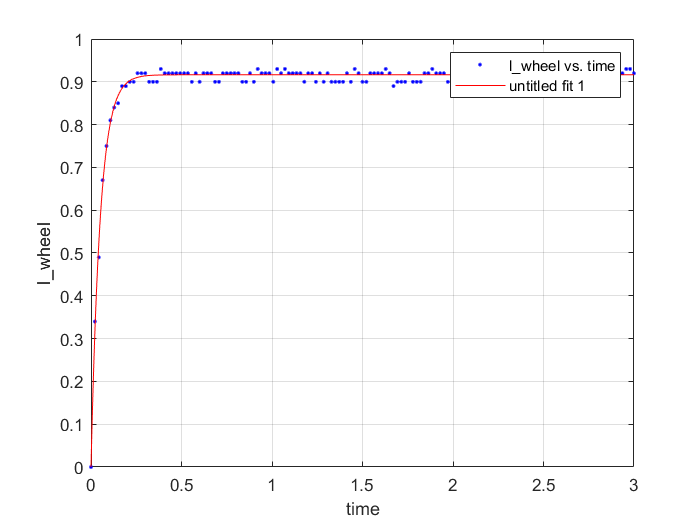

ans =      General model:
     ans(x) = a*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       T =       0.051  (0.04932, 0.05268)
       a =      0.9164  (0.9144, 0.9184)

createLWheelFit(time, l_wheel)

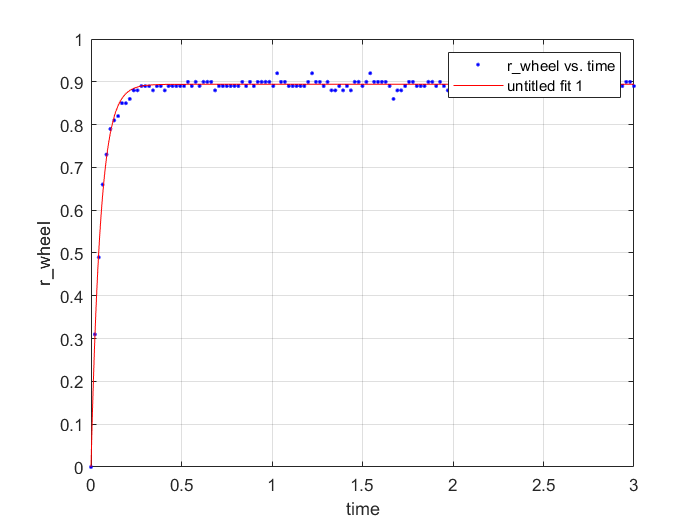

ans =      General model:
     ans(x) = a*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       T =     0.05191  (0.05049, 0.05333)
       a =      0.8942  (0.8926, 0.8958)

createRWheelFit(time, r_wheel)

Frequency Calibration:

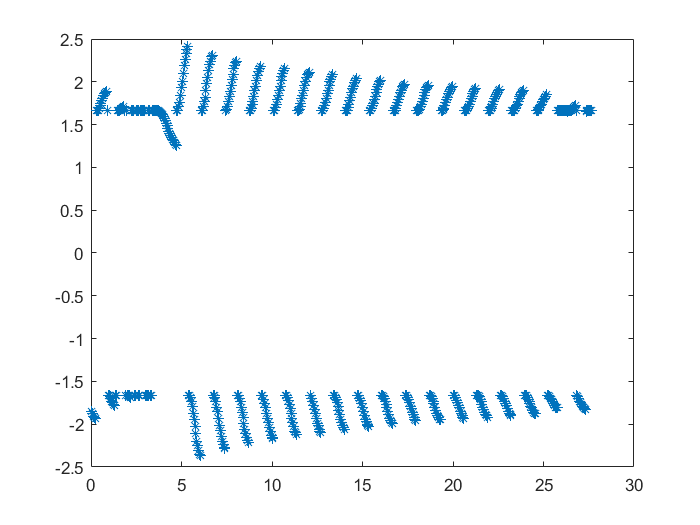

clf;
time = 0.05*[1:553];
plot(time, frequency_calibration_data, "*");


% From plot: found that x = 25.15 and x = 6.7 were 14 cycles apart:
Wn_cycles = (25.15 - 6.7)/14;          % radians per second
Wn = 2*pi*Wn_cycles;
L_eff = 9.81/(Wn^2);

Functions for Making Curve Fit Plots

function [fitresult, gof] = createLWheelFit(time, l_wheel)
%CREATEFIT(TIME,L_WHEEL)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : time
%      Y Output: l_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 27-Feb-2023 11:34:30


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( time, l_wheel );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.278498218867048 0.128610587325334];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'l_wheel vs. time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'l_wheel', 'Interpreter', 'none' );
grid on

end

function [fitresult, gof] = createRWheelFit(time, r_wheel)
%CREATEFIT(TIME,R_WHEEL)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : time
%      Y Output: r_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 27-Feb-2023 11:37:35


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( time, r_wheel );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.546881519204984 0.957506835434298];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'r_wheel vs. time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'r_wheel', 'Interpreter', 'none' );
grid on

end